% Définir les symboles pour les angles d'articulation
syms theta1 theta2 theta3 theta4;

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras

% Définir la position désirée de l'effecteur
x_desired = 1;
y_desired = 6;


%ESPACE DE TRAVAIL ET VERIFICATION
% Initialiser une liste pour stocker les coordonnées atteignables
reachable_points = [];

% Définir la grille d'angles d'articulation
theta1_range = linspace(-pi, pi, 10);
theta2_range = linspace(-pi, pi, 10);
theta3_range = linspace(-pi, pi, 10);


% Calculer les coordonnées atteignables pour chaque combinaison d'angles
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        for k = 1:length(theta3_range)
            
                % Calculer les coordonnées de l'effecteur
                x = a1 * cos(theta1_range(i)) + a2 * cos(theta1_range(i) + theta2_range(j)) + a3 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k));
                y = a1 * sin(theta1_range(i)) + a2 * sin(theta1_range(i) + theta2_range(j)) + a3 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k));
                
                % Ajouter les coordonnées à la liste
                reachable_points = [reachable_points; x, y];
            
        end
    end
end
min_x = min(reachable_points(:, 1));
max_x = max(reachable_points(:, 1));
min_y = min(reachable_points(:, 2));
max_y = max(reachable_points(:, 2));

% Vérifier si le point désiré est dans l'espace de travail
if x_desired < min_x || x_desired > max_x || y_desired < min_y || y_desired > max_y
    disp('Le point désiré est en dehors de l''espace de travail du robot.');
    return; % Sortir du programme
else
    disp('Le point désiré est dans l''espace de travail du robot. Continuer le calcul des angles d''articulation.');
    % Ajoutez votre code pour continuer le calcul des angles d'articulation ici
end

Le point désiré est dans l'espace de travail du robot. Continuer le calcul des angles d'articulation.


% Initialiser une figure
figure;
hold on;
% Tracer le nuage de points représentant l'espace de travail atteignable
scatter(reachable_points(:, 1), reachable_points(:, 2), 3, 'filled');
% Tracer le point désiré en rouge
plot(x_desired, y_desired, 'ro', 'MarkerSize', 10, 'DisplayName', 'Point désiré');

%RECHERCHE DE SOLUTIONS
% Initialiser une liste pour stocker les configurations atteignables
all_solutions = [];

% Définir une fonction pour la cinématique inverse
inverse_kinematics = @(x_desired, y_desired) find_inverse_kinematics(a1, a2, a3, x_desired, y_desired);

% Nombre de configurations à rechercher
num_configurations = 1; % Modifier selon vos besoins

% Recherche des configurations
for i = 1:num_configurations
    % Utiliser la fonction de cinématique inverse pour trouver une solution
    [theta1, theta2, theta3] = inverse_kinematics(x_desired, y_desired);
    
    % Calculer les coordonnées de l'effecteur pour cette configuration
    x_effecteur = a1 * cos(theta1) + a2 * cos(theta1 + theta2) + a3 * cos(theta1 + theta2 + theta3);
    y_effecteur = a1 * sin(theta1) + a2 * sin(theta1 + theta2) + a3 * sin(theta1 + theta2 + theta3);
    
    % Stocker la solution et les coordonnées de l'effecteur
    all_solutions = [all_solutions; [theta1, theta2, theta3, x_effecteur, y_effecteur]];
end

Convergence atteinte.



% Afficher toutes les configurations trouvées
disp('Configurations possibles du robot pour la position désirée :');

Configurations possibles du robot pour la position désirée :


disp('    Theta1   Theta2   Theta3    X_calculated   Y_calculated');

    Theta1   Theta2   Theta3    X_calculated   Y_calculated


disp(all_solutions);

    0.5563    1.1982   -0.1085    1.0000    6.0000



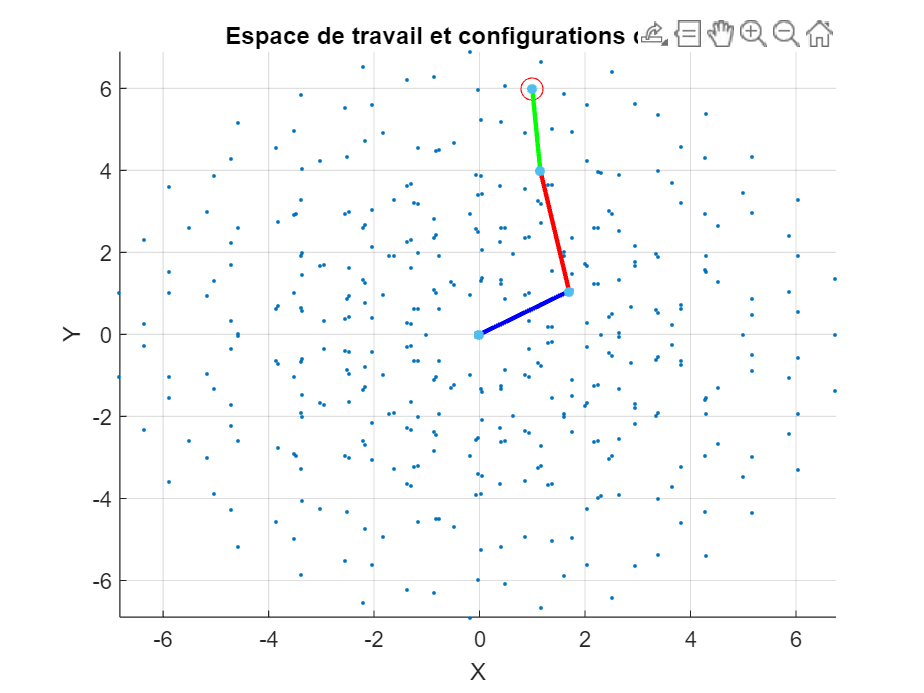




% Définir les couleurs pour chaque type de segment
color_segment_OA = 'b'; % Segment OA
color_segment_AB = 'r'; % Segment AB
color_segment_BC = 'g'; % Segment BC

% Visualisation des configurations du robot
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    
    % Calculer les positions des articulations
    O = [0, 0]; % Position de l'origine
    A = [a1 * cos(theta1), a1 * sin(theta1)]; % Position de l'articulation A
    B = A + [a2 * cos(theta1 + theta2), a2 * sin(theta1 + theta2)]; % Position de l'articulation B
    C = B + [a3 * cos(theta1 + theta2 + theta3), a3 * sin(theta1 + theta2 + theta3)]; % Position de l'articulation C (effecteur)

    % Tracer le robot pour cette configuration
    plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'DisplayName', ['Segment OA - Solution ', num2str(i)]);
    plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'DisplayName', ['Segment AB - Solution ', num2str(i)]);
    plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'DisplayName', ['Segment BC - Solution ', num2str(i)]);
    scatter([O(1), A(1), B(1), C(1)], [O(2), A(2), B(2), C(2)], 20, 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]);
end

% Calculer les limites des axes
xlim([min(reachable_points(:, 1)), max(reachable_points(:, 1))]);
ylim([min(reachable_points(:, 2)), max(reachable_points(:, 2))]);

% Configurer le titre et les étiquettes des axes
title('Espace de travail et configurations du robot');
xlabel('X');
ylabel('Y');

% Affichage de la grille
grid on;

hold off;

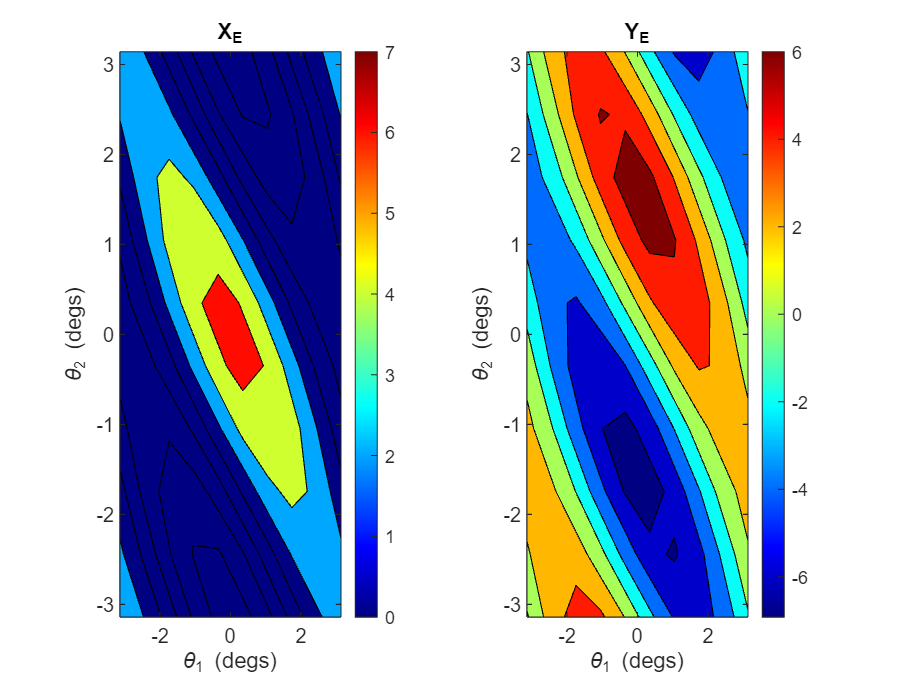


% Calculez les coordonnées de l'effecteur final pour chaque combinaison d'angles
X_coordinates = zeros(length(theta1_range), length(theta2_range));
Y_coordinates = zeros(length(theta1_range), length(theta2_range));
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        % Calculez les coordonnées de l'effecteur final en fonction des angles articulaires
        X_coordinates(i, j) = a1 * cos(theta1_range(i)) + a2 * cos(theta1_range(i) + theta2_range(j)) + a3 * cos(theta1_range(i) + theta2_range(j) + theta3);
        Y_coordinates(i, j) = a1 * sin(theta1_range(i)) + a2 * sin(theta1_range(i) + theta2_range(j)) + a3 * sin(theta1_range(i) + theta2_range(j) + theta3);
    end
end

% Visualisez les coordonnées de l'effecteur final
plot_XY_given_theta_2dof(theta1_range, theta2_range, X_coordinates, Y_coordinates, (a1 + a2 + a3));

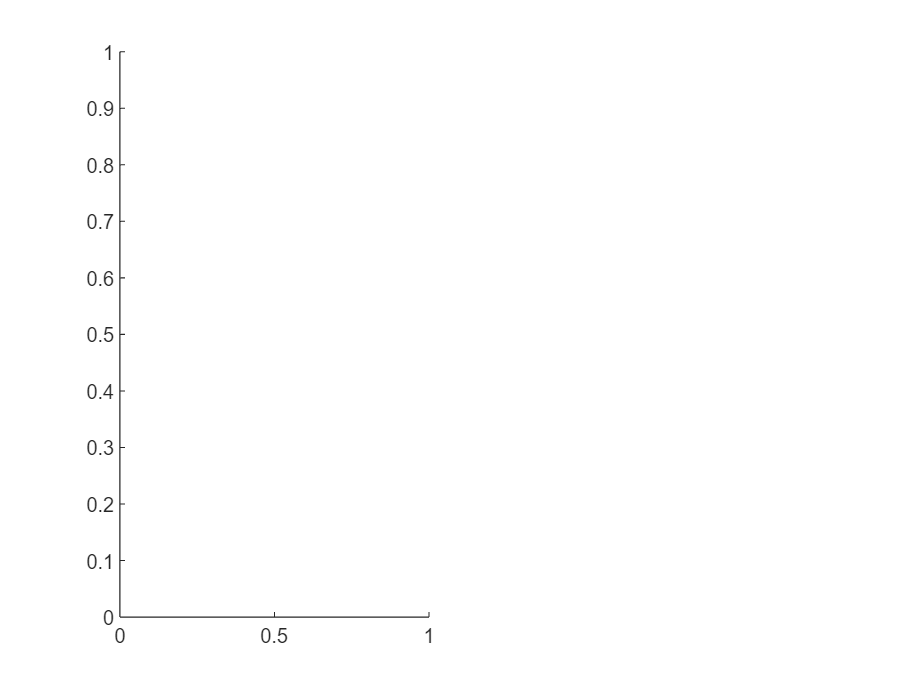



% Créer une nouvelle figure pour la visualisation tridimensionnelle
figure;

% Tracer la surface tridimensionnelle des coordonnées X en fonction de θ1 et θ2
subplot(1, 2, 1);

surf(theta1_mesh, theta2_mesh, X_coordinates);

Unrecognized function or variable 'theta1_mesh'.

xlabel('\theta_1');
ylabel('\theta_2');
zlabel('X');
title('Coordonnées X en fonction de \theta_1 et \theta_2');

% Tracer la surface tridimensionnelle des coordonnées Y en fonction de θ1 et θ2
subplot(1, 2, 2);
surf(theta1_mesh, theta2_mesh, Y_coordinates);
xlabel('\theta_1');
ylabel('\theta_2');
zlabel('Y');
title('Coordonnées Y en fonction de \theta_1 et \theta_2');



% Fonction pour la cinématique inverse

function plot_XY_given_theta_2dof(theta_1_mat_degs,theta_2_mat_degs,...
                                  X_mat,Y_mat,a_cmax)
                              
xlab_str = '\theta_1 (degs)';
ylab_str = '\theta_2 (degs)';

figure;
hax(1) = subplot(1,2,1);
   contourf(theta_1_mat_degs, theta_2_mat_degs, X_mat);
      clim(hax(1), [0 a_cmax]);
      colormap(gca,'jet'); colorbar
      xlabel(xlab_str, 'Interpreter', 'tex');
      ylabel(ylab_str, 'Interpreter', 'tex');
      title(hax(1), 'X_E', 'Interpreter', 'tex')
hax(2) = subplot(1,2,2);
   contourf(theta_1_mat_degs, theta_2_mat_degs, Y_mat); 
      clim(hax(1), [0 a_cmax]);
      colormap(gca,'jet'); colorbar
      xlabel(xlab_str, 'Interpreter', 'tex');
      ylabel(ylab_str, 'Interpreter', 'tex');
      title(hax(2), 'Y_E', 'Interpreter', 'tex')

end

function [theta1, theta2, theta3] = find_inverse_kinematics(a1, a2, a3, x_desired, y_desired)
    % Définir les angles d'articulation
    syms theta1 theta2 theta3;

    % Définir une tolérance et un nombre maximum d'itérations
    tolerance = 0.00001;
    max_iterations = 100;

    % Initialiser les angles d'articulation
    theta1 =0; % Initialiser à des valeurs aléatoires
    theta2 =0;
    theta3 =0;
    

    % Boucle d'itération pour trouver les angles d'articulation
    for i = 1:max_iterations
        % Calculer les équations directes de cinématique directe
        x = a1 * cos(theta1) + a2 * cos(theta1 + theta2) + a3 * cos(theta1 + theta2 + theta3);
        y = a1 * sin(theta1) + a2 * sin(theta1 + theta2) + a3 * sin(theta1 + theta2 + theta3);

        % Calculer l'erreur de position
        error_x = x_desired - x;
        error_y = y_desired - y;
        error = [error_x; error_y];

        % Calculer les dérivées partielles
        dx_dtheta1 = -a1 * sin(theta1) - a2 * sin(theta1 + theta2) - a3 * sin(theta1 + theta2 + theta3);
        dx_dtheta2 = -a2 * sin(theta1 + theta2) - a3 * sin(theta1 + theta2 + theta3);
        dx_dtheta3 = -a3 * sin(theta1 + theta2 + theta3);
        

        dy_dtheta1 = a1 * cos(theta1) + a2 * cos(theta1 + theta2) + a3 * cos(theta1 + theta2 + theta3);
        dy_dtheta2 = a2 * cos(theta1 + theta2) + a3 * cos(theta1 + theta2 + theta3);
        dy_dtheta3 = a3 * cos(theta1 + theta2 + theta3);
        

        % Construire la Jacobienne
        J = [dx_dtheta1, dx_dtheta2, dx_dtheta3; 
             dy_dtheta1, dy_dtheta2, dy_dtheta3];

        % Vérifier la convergence
        if norm(error) < tolerance
            disp('Convergence atteinte.');
            break;
        end

        % Calculer la variation des angles d'articulation
        delta_theta = pinv(J) * error;

        % Mettre à jour les angles d'articulation
        theta1 = theta1 + delta_theta(1);
        theta2 = theta2 + delta_theta(2);
        theta3 = theta3 + delta_theta(3);
       
    end
end
